# Karakteristika

Fs = 1;
Ts = 1/Fs;
T = 200;
t = 0:Ts:T;
N = length(t);
F = 1 / (N * T);
fmax = 1/(2*T);
v = 0:F:(fmax - F); %frequency vector
u = ones(1,(T*Fs)+1);
simin = [t',u'];

% open_system("seminar_simulink")
simy = [];
for i = 0:0.1:2.5
    u = ones(1,(T*Fs)+1)*i;
    simin = [t',u'];
    set_param('seminar_simulink','StopTime',int2str(T));
    sim("seminar_simulink");
    simy = [ans.simouty.Data,simy];
end

open_system("seminar_simulink")

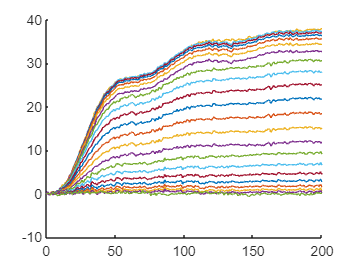

figure;
hold on;
for i = 1:length(simy(1,:))
    plot(t',simy(:,i));
end

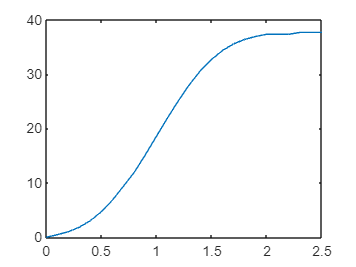

const = [];
for i = 1:length(simy(1,:))
    const = [mean(simy(end-20:end,i)),const];
end
figure
plot(0:0.1:2.5,const)

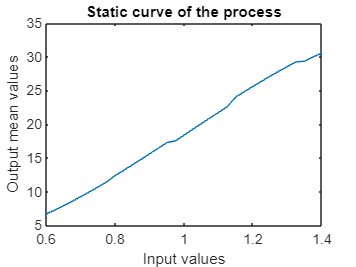

% open_system("seminar_simulink")
simy_short = [];
for i = 0.6:0.025:1.4
    u = ones(1,(T*Fs)+1)*i;
    simin = [t',u'];
    set_param('seminar_simulink','StopTime',int2str(T));
    sim("seminar_simulink");
    simy_short = [ans.simouty.Data,simy_short];
end
const_short = [];
for i = 1:length(simy_short(1,:))
    const_short = [mean(simy_short(end-20:end,i)),const_short];
end
figure
plot(0.6:0.025:1.4,const_short)
xlabel("Input values")
ylabel("Output mean values")
title("Static curve of the process")

open_system("seminar_simulink");

## Frekvenčni Odziv in noise

Fs = 0.0625;
Ts = 1/Fs;
T = 19200;
t = 0:Ts:T;
N = length(t);
F = 1 / (N * T);
fmax = 1/(2*T);
v = 0:F:(fmax - F); %frequency vector
u = zeros(1,(T*Fs)+1);
simin = [t',u'];

% open_system("seminar_simulink");
set_param('seminar_simulink','StopTime',int2str(T));
sim("seminar_simulink");
Noise = ans.simouty.Data;

U_PRBS = 0.6 + prbs(10)*0.8;
U_const = ones(length(t)-length(U_PRBS),1);
simin_PRBS = [U_const;U_PRBS];
simin = [t',simin_PRBS];
% open_system("seminar_simulink");
set_param('seminar_simulink','StopTime',int2str(T));
sim("seminar_simulink");
simy_PRBS = [simin,ans.simouty.Data];

t = simy_PRBS(1:end-178,1);
u = simy_PRBS(179:end,2)-1;
y = simy_PRBS(179:end,3)-19.1;
yNoise = Noise(179:end);

% t = simy_PRBS(:,1);
% u = simy_PRBS(:,2)-1;
% y = simy_PRBS(:,3)-19.1;

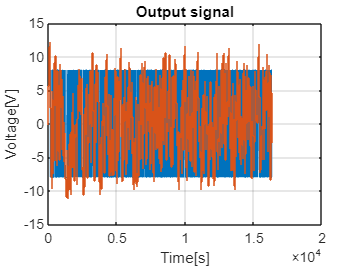

figure
plot(t,u*20)
hold on
stairs(t,y)
xlabel('Time[s]');
ylabel('Voltage[V]');
title('Output signal');
grid on;

N = length(t);
T = t(2,1) - t(1,1);
F = 1 / (N * T);
fmax = 1/(2*T);
v = 0:F:(fmax - F+F); %frequency vector

## FFT

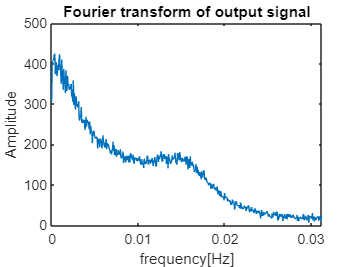

FT_input = fft(u);
FT_output = fft(y);

figure;
plot(v,abs(FT_output(1:(end+1)/2)))
title("Fourier transform of output signal")
xlabel("frequency[Hz]")
ylabel("Amplitude")

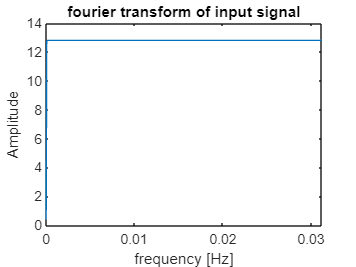


plot(v,abs(FT_input(1:(end+1)/2)))
title("fourier transform of input signal")
xlabel("frequency [Hz]")
ylabel("Amplitude")

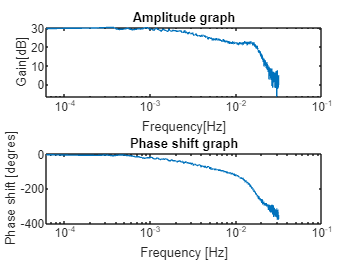


G_jw = FT_output ./ FT_input;
Faza = unwrap(angle(G_jw));

subplot(2,1,1), semilogx(v,20*log10(abs(G_jw(1:(end+1)/2))))
title("Amplitude graph")
xlabel("Frequency[Hz]")
ylabel("Gain[dB]")
subplot(2,1,2), semilogx(v,180/pi*(Faza(1:(end+1)/2)))
title("Phase shift graph")
xlabel("Frequency [Hz]")
ylabel("Phase shift [degres]")

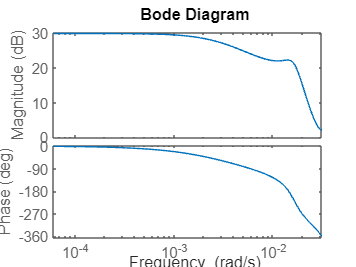

n = 3;
d = 0;
N = length(y);
num_columns = 1 + n + d;
num_rows = N - n - d; 
k = d + n + 1;
psi = [];

for i = 1:n
    psi = [psi, -y(k-i:N-i)];
end

for i = 1:n
    psi =[psi,u(k-d-i:N-d-i)];
end

y_short = y((n+d+1):end);
Th = psi \ y_short;
T = T*2*pi;
numerator = Th(n+1:(n*2));
denominator = [1; Th(1:n)];
G = tf(numerator', denominator', T);
G.inputdelay = d;


N = length(t);
T = t(2,1) - t(1,1);
F = 1 / (N * T);
fmax = 1/(2*T);
v = 0:F:(fmax - F + F); %frequency vector

figure
bode(G,v);

[MAG, PH]=bode(G, v);
MAG = MAG(:);
PH = PH(:);
FT_input = fft(u);
FT_output = fft(y);

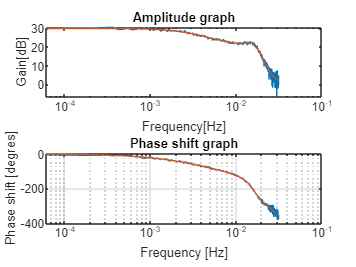

% G_jw = FT_output ./ FT_input;
% faza = unwrap(angle(G_jw));
figure

subplot(2,1,1), semilogx(v,20*log10(abs(G_jw(1:(end+1)/2))))
hold on
subplot(2,1,1), semilogx(v,20*log10(MAG))
title("Amplitude graph")
xlabel("Frequency[Hz]")
ylabel("Gain[dB]")

subplot(2,1,2), semilogx(v,180/pi*(Faza(1:(end+1)/2)))
hold on
subplot(2,1,2), semilogx(v,PH)
grid
title("Phase shift graph")
xlabel("Frequency [Hz]")
ylabel("Phase shift [degres]")

## Parametric model 

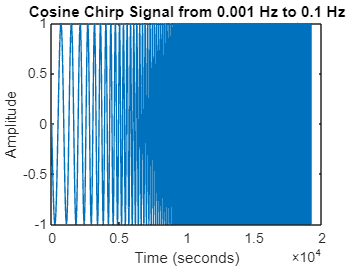

Fs = 10; % Increase the sampling frequency for better resolution
Ts = 1/Fs;
T = 19200;                 % Total time in seconds
t = 0:Ts:T;
% Frequency range
f0 = 0.001;              % Start frequency in Hz
f1 = 0.1;                 % End frequency in Hz

% Generate the cosine chirp signal
% Adding 'phase', pi/2 to generate a cosine instead of a sine wave chirp
signal = chirp(t, f0, T, f1, 'logarithmic', 90); % phase in degrees

% Plot the signal
figure;
plot(t, signal);
title('Cosine Chirp Signal from 0.001 Hz to 0.1 Hz');
xlabel('Time (seconds)');
ylabel('Amplitude');


% Optionally, you can listen to the signal if you want to check its acoustic characteristics
% sound(signal, Fs); % Uncomment this line if you want to listen to the signal

temp = (signal*0.4)'+1;
oness = ones(1,6000);
U_true = [oness';temp];
t = 0:Ts:19200 + 600;
simin = [t', U_true];

%v simulinku spremeni čas na 260
% sampling rate pa je 0.01
set_param('seminar_simulink','StopTime',int2str(19200 + 600));
sim("seminar_simulink");
exp_true = [simin,ans.simouty.Data];


t = simy_PRBS(1:end-178,1);
u = simy_PRBS(179:end,2)-1;
y = simy_PRBS(179:end,3)-19.4;

tm = exp_true(1:end-6001,1);
um = exp_true(6002:end,2)-1;
ym = exp_true(6002:end,3)-19.4;

% figure
% plot(tm,um)
% figure
% plot(t,u)
% % hold on 
% % grid on
% % stairs(t,y)
% ylim([-1 1])
% title("Identification input signal")
% xlabel("Time[s]")
% ylabel("Voltage[V]")
% % 
% % figure
% % plot(tm,-um)
% % hold on 
% % grid on
% % stairs(tm,ym)

N = length(t);
T = t(2,1) - t(1,1);
F = 1 / (N * T);
fmax = 1/(2*T);
v = 0:F:(fmax - F + F); %frequency vector

Nm = length(tm);
Tm = tm(2,1) - tm(1,1);
Fm = 1 / (Nm * Tm);
fmaxm = 1/(2*Tm);
vm = 0:Fm:(fmaxm - Fm); %frequency vector

## FFT

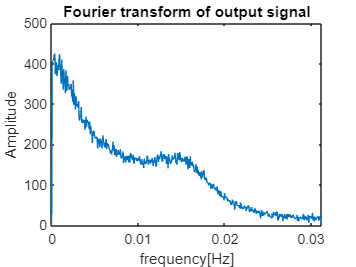

FT_input = fft(u);
FT_output = fft(y);

figure;
plot(v,abs(FT_output(1:(end+1)/2)))
title("Fourier transform of output signal")
xlabel("frequency[Hz]")
ylabel("Amplitude")


plot(v,abs(FT_input(1:(end+1)/2)))
title("fourier transform of input signal")
xlabel("frequency [Hz]")
ylabel("Amplitude")

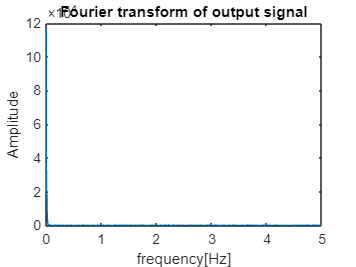


FT_input_m = fft(um);
FT_output_m = fft(ym);

figure;
plot(vm,abs(FT_output_m(1:end/2)))
title("Fourier transform of output signal")
xlabel("frequency[Hz]")
ylabel("Amplitude")

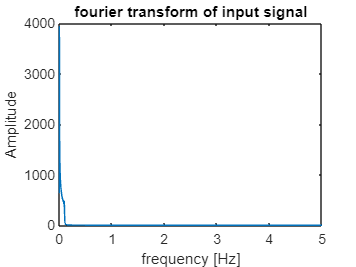


plot(vm,abs(FT_input_m(1:end/2)))
title("fourier transform of input signal")
xlabel("frequency [Hz]")
ylabel("Amplitude")

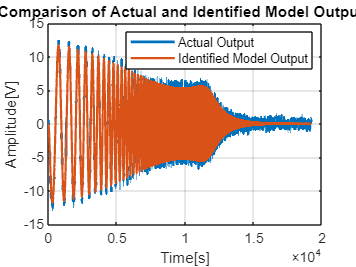

n = 3;
d = 0;
N = length(y);
num_columns = 1 + n + d;
num_rows = N - n - d; 
k = d + n + 1;
psi = [];

for i = 1:n
    psi = [psi, -y(k-i:N-i)];
end

for i = 1:n
    psi =[psi,u(k-d-i:N-d-i)];
end

T = t(2,1) - t(1,1);

y_short = y((n+d+1):end);
Th = psi \ y_short;
Tmp = T;

numerator = Th(n+1:(n*2));
denominator = [1; Th(1:n)];
Gm = tf(numerator', denominator', Tmp);
Gm.inputdelay = d;

figure
G_res = d2d(Gm, 0.1);
% bode(G_resampled,v);
[MAG_res, PH_res]=bode(G_res, v);
MAG_res = MAG_res(:);
PH_res = PH_res(:);

% G_resampled.inputdelay = 2
ymm = lsim(G_res, um, tm);
figure;
plot(tm, ym, 'LineWidth', 2);
hold on;
plot(tm, ymm, 'LineWidth', 1.5);
xlabel('Time[s]');
ylabel('Amplitude[V]');
legend('Actual Output', 'Identified Model Output');
title('Comparison of Actual and Identified Model Outputs');
grid on;


error = ymm - ym;
std_dev = std(error);
disp(['Standard Deviation of the Error: ', num2str(std_dev)]);

Standard Deviation of the Error: 0.35124


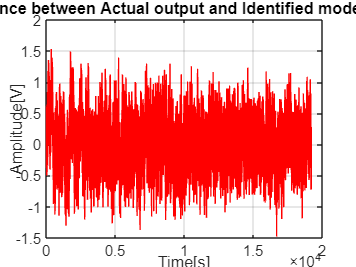

figure
plot(tm, error,"r");
xlabel('Time[s]');
ylabel('Amplitude[V]');
title('Difference between Actual output and Identified model output');
grid on;

% Calculate residuals
y_pred = psi * Th;  % Predicted outputs using the model
residuals = y_short - y_pred;

% Estimate the variance of the residuals
N = size(psi, 1);   % Number of observations
p = size(Th, 1);    % Number of parameters
sigma2 = (residuals' * residuals) / (N - p);

% Calculate covariance matrix of the parameter estimates
Cov_Theta = sigma2 * pinv(psi' * psi);

% Compute standard deviations of the estimates
std_Theta = sqrt(diag(Cov_Theta));

% Display the standard deviations
disp('Standard deviations of the parameters:');

Standard deviations of the parameters:


disp(std_Theta);

    0.0069
    0.0056
    0.0029
    0.0235
    0.0308
    0.0589



## Noise

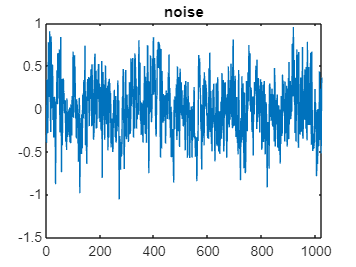

figure
plot(yNoise)
title("noise")


fftNoise = fft(yNoise);
plot(v,abs(fftNoise(1:(end+1)/2)))
title("fourier transformed noise")

hold on

N0 = 35;
N_inf = 10;

wg = 0.003;

%Ng = abs(Noise(wg));
approx = N_inf + ((N0 - N_inf)./sqrt(1 + pow2(v/wg)))

approx =    27.6777   27.6152   27.5525   27.4895   27.4264   27.3631   27.2995   27.2358   27.1719   27.1078   27.0435   26.9790   26.9144   26.8495   26.7846   26.7194   26.6541   26.5887   26.5231   26.4573   26.3914   26.3254   26.2592   26.1930   26.1266   26.0600   25.9934   25.9267   25.8598   25.7929   25.7259   25.6588   25.5916   25.5243   25.4569   25.3895   25.3220   25.2545   25.1868   25.1192   25.0515   24.9837   24.9160   24.8481   24.7803   24.7124   24.6445   24.5766   24.5087   24.4408


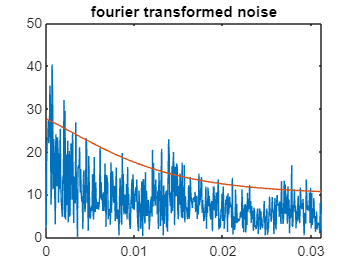

plot(v, approx)

## Standard deviation of the error

d_G = (abs(approx))./abs(FT_output(1:(end+1)/2))'

d_G =    12.2067    0.0697    0.0679    0.0676    0.0664    0.0648    0.0643    0.0729    0.0706    0.0673    0.0733    0.0716    0.0680    0.0698    0.0653    0.0632    0.0688    0.0697    0.0759    0.0646    0.0699    0.0727    0.0783    0.0678    0.0731    0.0738    0.0797    0.0676    0.0755    0.0776    0.0696    0.0745    0.0730    0.0756    0.0761    0.0743    0.0738    0.0723    0.0791    0.0786    0.0820    0.0697    0.0840    0.0760    0.0808    0.0863    0.0772    0.0813    0.0834    0.0829


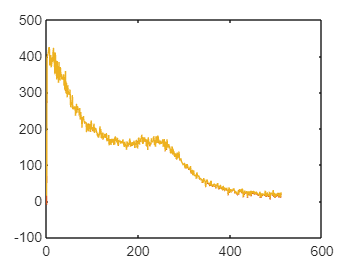


figure
plot(abs(FT_output(1:(end+1)/2)))
hold on
plot(abs(FT_output(1:(end+1)/2)) - d_G')
plot(abs(FT_output(1:(end+1)/2)) + d_G')

## stochastic 

% Initialize parameters
T = t(2,1) - t(1,1);
n = 3; % Order of the system
d=1;
theta = zeros(n*2,1); % Initial parameter guess ([a1, a2, a3, b0, b1, b2])
P = 1000*eye(n*2); % Initial covariance matrix
lambda = 0.98; % Forgetting factor

% Initialize data vectors
phi = zeros(n*2,1); % Regression vector
Y = zeros(length(u),1); % To store estimated output

% Recursive Least Squares estimation
for k = n+1:length(u)
    % Update regression vector
    phi_y = -y(k-1:-1:k-n); % Y part of the regression vector
    phi_u = u(k-n-d+1:k-d); % U part of the regression vector (includes u(k))
    phi = [phi_y; phi_u]; % Combine both parts
    
    % Compute the output estimation
    Y(k) = phi' * theta;
    
    % Update the covariance matrix
    P = (P - (P * (phi * phi') * P) / (lambda + phi' * P * phi)) / lambda;
    
    % Update the parameter estimate
    theta = theta + P * phi * (y(k) - Y(k));
end

% Display estimated parameters
disp('Estimated parameters:');

Estimated parameters:


disp(theta);

   -0.6724
    0.4391
   -0.3487
    1.9612
    7.9300
    3.0044




numerator = theta(n+1:(n*2));
denominator = [1; theta(1:n)];
G_est = tf(numerator', denominator', T*2*pi);
G_est.inputdelay = d

G_est =
 
                1.961 z^2 + 7.93 z + 3.004
  z^(-1) * ------------------------------------
           z^3 - 0.6724 z^2 + 0.4391 z - 0.3487
 
Sample time: 100.53 seconds
Discrete-time transfer function.
Model Properties


[MAG_est, PH_est]=bode(G_est, v);
MAG_est = MAG_est(:);
PH_est = PH_est(:);

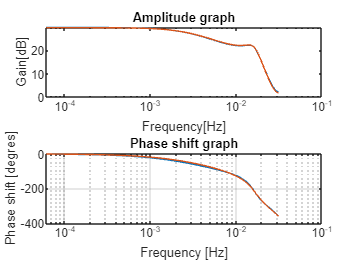

N = length(t);
T = t(2,1) - t(1,1);
F = 1 / (N * T);
fmax = 1/(2*T);
v = 0:F:(fmax - F + F); %frequency vector

figure
subplot(2,1,1), semilogx(v,20*log10(MAG))
hold on
subplot(2,1,1), semilogx(v,20*log10(MAG_est))
title("Amplitude graph")
xlabel("Frequency[Hz]")
ylabel("Gain[dB]")

subplot(2,1,2), semilogx(v,PH)
hold on
subplot(2,1,2), semilogx(v,PH_est/(1.5))
grid
title("Phase shift graph")
xlabel("Frequency [Hz]")
ylabel("Phase shift [degres]")

## ortogonal corelation

n=5000;
% Process model (continuous transfer function numerator and denominator)
% Number and values of test frequencies
N = 20;
f=3*logspace(-4,-2,N);
Stevilo_period_opazovanja = round(linspace(2,30,N));
ampl = nan(1,N); faza = nan(1,N);
for i=1:N
    % definiramo vhodni signal; casovna os se prilagaja frekvenci
    Perioda = 1/f(i);
    % zacetni cas je vsaj 300 sek, da minejo prehodni pojavi
    t_zacetni = 300;
    Zacetnih_period = ceil(t_zacetni/Perioda);
    % zacetni cas mora biti na zacetku periode
    t_zacetni = Zacetnih_period * Perioda;
    t_koncni = t_zacetni + Stevilo_period_opazovanja(i) * Perioda;
    t=linspace(0,t_koncni,n)';
    %
    % vhodni signal je cosinus
    x=1+(cos(2*pi*f(i)*t)*0.4);
    %
    % Za izracun bomo rabili se sinus
    x1=1+(sin(2*pi*f(i)*t)*0.4);
    %
    % Indeksi zacetka in konca prikazanega signala
    ind1 = round(t_zacetni/t(2));
    ind3 = round(t_koncni/t(2));
    % izracunamo izhodni signal in ga zmotimo s sumom
    simin = [t,x];
    Ts = (t(3)-t(2));
    set_param('seminar_simulink','StopTime',int2str(t(end)));
    sim("seminar_simulink");
    y = ans.simouty.Data;

    re=((y(ind1:ind3)-19.4))'*((x(ind1:ind3)-1)*2.5)*2/(ind3-ind1);
    im=-((y(ind1:ind3)-19.4))'*((x1(ind1:ind3)-1)*2.5)*2/(ind3-ind1);
    ampl(i)=sqrt(re^2+im^2);
    faza(i)=atan2(im,re);
end 
faza=unwrap(faza);

## plot

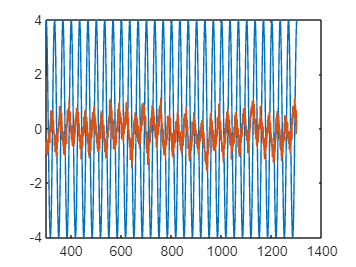

figure;
plot(t(ind1:ind3),((x(ind1:ind3)-1)*10))
hold on
plot(t(ind1:ind3),y(ind1:ind3)-19.4)

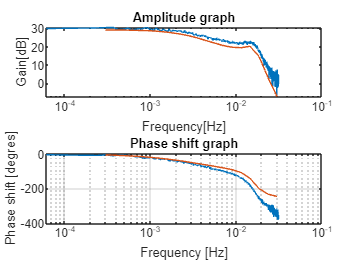

figure

subplot(2,1,1), semilogx(v,20*log10(abs(G_jw(1:(end+1)/2))))
hold on
subplot(2,1,1), semilogx(f,(20+2*pi)*log10(ampl))
% subplot(2,1,1), semilogx(v,20*log10(MAG))
title("Amplitude graph")
xlabel("Frequency[Hz]")
ylabel("Gain[dB]")

subplot(2,1,2), semilogx(v,180/pi*(Faza(1:(end+1)/2)))
hold on
subplot(2,1,2), semilogx(f,180/pi*faza)
% subplot(2,1,2), semilogx(v,PH)
grid
title("Phase shift graph")
xlabel("Frequency [Hz]")
ylabel("Phase shift [degres]")